# **Metoda Powella**

clearvars all; close all;

f = @(x) x(1)^2 + x(2)^2 - 400/(100*x(1)^2 + x(2)^2 + 1);

eps = 1e-3; x0 = [0.25; 0.5];
d = eye(length(x0));
Nmax = 100;

[x_min, iterations] = powell(f, x0, d, eps, Nmax)

x_min = 	1.0e+-15 *

   -0.1665
   -0.4441


iterations = 2

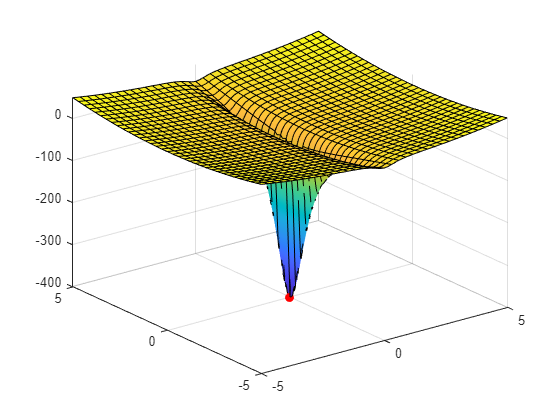


fun = @(x, y) x.^2 + y.^2 - 400./(100*x.^2 + y.^2 + 1);
figure()
fsurf(fun); hold on;
plot3(x_min(1), x_min(2), f(x_min), 'r.', MarkerSize=20);

P0 = [0.25; 0.5]; P1 = [-0.1; -0.1];

f = @(x) 2.5*(x(1).^2-x(2)).^2+(1-x(1)).^2 

f = function_handle with value:
    @(x)2.5*(x(1).^2-x(2)).^2+(1-x(1)).^2



[x_p0, iterations] = powell(f, P0, d, eps, Nmax)

x_p0 =     1.0000
    1.0000


iterations = 4

[x_p1, iterations] = powell(f, P1, d, eps, Nmax)

x_p1 =     0.9988
    0.9973


iterations = 3


fun = @(x1,x2) 2.5*(x1.^2-x2).^2+(1-x1).^2 

fun = function_handle with value:
    @(x1,x2)2.5*(x1.^2-x2).^2+(1-x1).^2


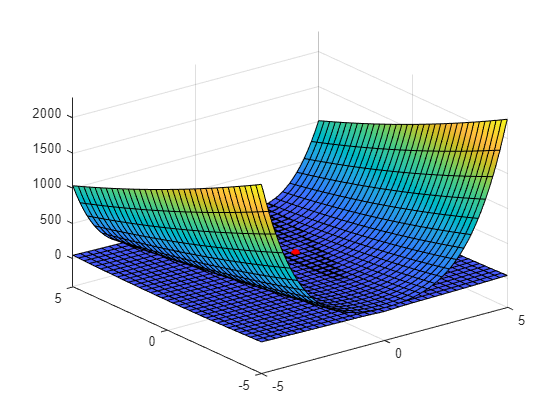

fsurf(fun)
plot3(x_p0(1), x_p0(2), f(x_min), 'r.', MarkerSize=20);
plot3(x_p1(1), x_p1(2), f(x_min), 'r.', MarkerSize=20);